
clear;clc;close all
load('wks_cshot.mat');

kpts_types_icp = cshotmugicp{:,{'KP_Tipe'}};
kpts_rad_icp = cshotmugicp{:,{'KP_RAD'}};
desc_rad_icp = cshotmugicp{:,{'DESC_RAD'}};
inlier_rad_icp = cshotmugicp{:,{'INLIER_RAD'}};
dist_mm_icp = cshotmugicp{:,{'DISTmm'}};

for i = 1:length(dist_mm_icp)
    if dist_mm_icp(i,1) > 1000
        dist_mm_icp(i,1) = NaN;
    end
end

kpts_types = cshotmug{:,{'KP_Tipe'}};
kpts_rad = cshotmug{:,{'KP_RAD'}};
desc_rad = cshotmug{:,{'DESC_RAD'}};
inlier_rad = cshotmug{:,{'INLIER_RAD'}};
dist_mm = cshotmug{:,{'DISTmm'}};

for i = 1:length(dist_mm)
    if dist_mm(i,1) > 1000
        dist_mm(i,1) = NaN;
    end
end

clear i;

disp('mug)')


%% iss
% clc;close all;
iss_index_icp = find(kpts_types_icp == 'iss');
iss_dist_icp = (dist_mm_icp(iss_index_icp(1,1):iss_index_icp(length(iss_index_icp),1),1));
iss_min_dist_icp = min(iss_dist_icp)

iss_min_dist_icp = 0

iss_max_dist_icp = max(iss_dist_icp)

iss_max_dist_icp = 0.5630

iss_middle_dist_icp = media(iss_dist_icp)

iss_middle_dist_icp = 0.2420

iss_nan_values_icp = length(find(isnan(iss_dist_icp) == 1))

iss_nan_values_icp = 0


iss_index = find(kpts_types == 'iss');
iss_dist = (dist_mm(iss_index(1,1):iss_index(length(iss_index),1),1));
iss_min_dist = min(iss_dist)

iss_min_dist = 0.0990

iss_max_dist = max(iss_dist)

iss_max_dist = 0.9120

iss_middle_dist = media(iss_dist)

iss_middle_dist = 0.4574

iss_nan_values = length(find(isnan(iss_dist) == 1))

iss_nan_values = 0

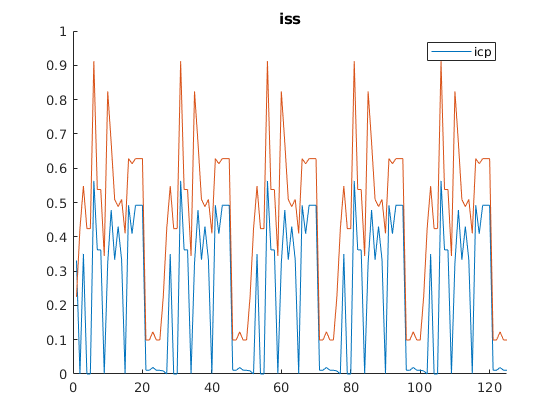


figure;
hold on;
plot(iss_dist_icp)
plot(iss_dist)
xlim([0 length(iss_dist)])
legend('icp')
title('iss')

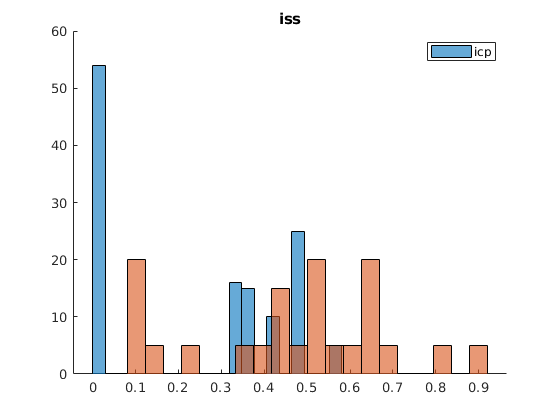


figure;
hold on;
histogram(iss_dist_icp,20)
histogram(iss_dist,20)
legend('icp')
title('iss')

hold off;


%% us
% clc;close all;
us_index_icp = find(kpts_types_icp == 'us');
us_dist_icp = (dist_mm_icp(us_index_icp(1,1):us_index_icp(length(us_index_icp),1),1));
us_min_dist_icp = min(us_dist_icp)

us_min_dist_icp = 0.3640

us_max_dist_icp = max(us_dist_icp)

us_max_dist_icp = 22.1120

us_middle_dist_icp = media(us_dist_icp)

us_middle_dist_icp = 13.8562

us_nan_values_icp = length(find(isnan(us_dist_icp) == 1))

us_nan_values_icp = 0


us_index = find(kpts_types == 'us');
us_dist = (dist_mm(us_index(1,1):us_index(length(us_index),1),1));
us_min_dist = min(us_dist)

us_min_dist = 0.4890

us_max_dist = max(us_dist)

us_max_dist = 37.9260

us_middle_dist = media(us_dist)

us_middle_dist = 23.4493

us_nan_values = length(find(isnan(us_dist) == 1))

us_nan_values = 0

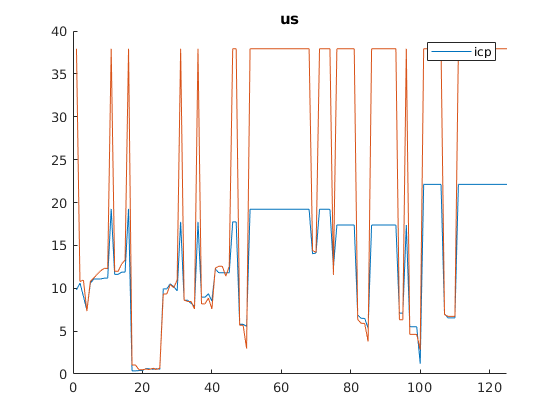


figure;
hold on;
plot(us_dist_icp)
plot(us_dist)
xlim([0 length(us_dist)])
legend('icp')
title('us')

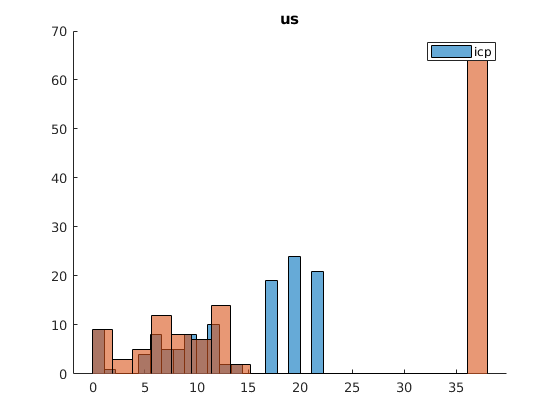


figure;
hold on;
histogram(us_dist_icp,20)
histogram(us_dist,20)
legend('icp')
title('us')

hold off;


%% susan
% clc;close all;
susan_index_icp = find(kpts_types_icp == 'susan');
susan_dist_icp = (dist_mm_icp(susan_index_icp(1,1):susan_index_icp(length(susan_index_icp),1),1));
susan_min_dist_icp = min(susan_dist_icp)

susan_min_dist_icp = 0.1170

susan_max_dist_icp = max(susan_dist_icp)

susan_max_dist_icp = 0.5500

susan_middle_dist_icp = media(susan_dist_icp)

susan_middle_dist_icp = 0.2818

susan_nan_values_icp = length(find(isnan(susan_dist_icp) == 1))

susan_nan_values_icp = 0


susan_index = find(kpts_types == 'susan');
susan_dist = (dist_mm(susan_index(1,1):susan_index(length(susan_index),1),1));
susan_min_dist = min(susan_dist)

susan_min_dist = 0.0890

susan_max_dist = max(susan_dist)

susan_max_dist = 1.2050

susan_middle_dist = media(susan_dist)

susan_middle_dist = 0.5146

susan_nan_values = length(find(isnan(susan_dist) == 1))

susan_nan_values = 0

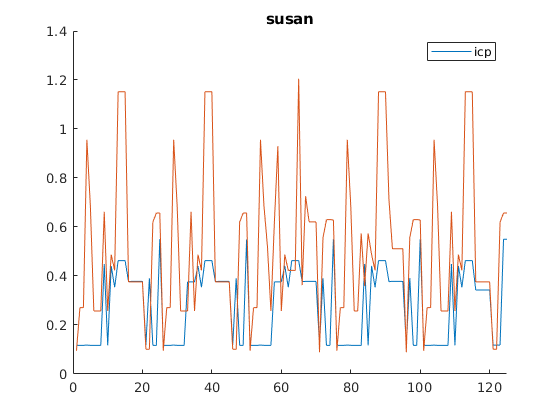


figure;
hold on;
plot(susan_dist_icp)
plot(susan_dist)
xlim([0 length(susan_dist)])
title('susan')
legend('icp')

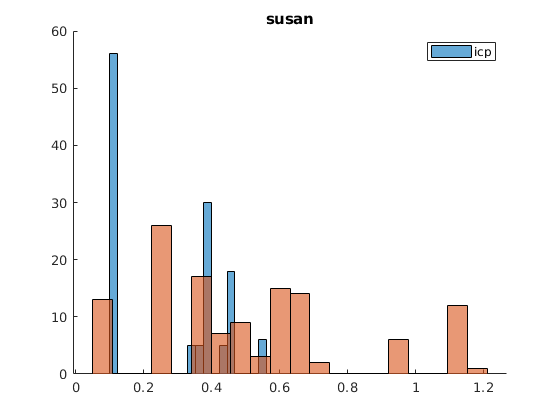

figure;
hold on;
histogram(susan_dist_icp,20)
histogram(susan_dist,20)
title('susan')
legend('icp')

hold off;



%% harris3D
% clc;close all;
harris3D_index_icp = find(kpts_types_icp == 'harris3D');
harris3D_dist_icp = (dist_mm_icp(harris3D_index_icp(1,1):harris3D_index_icp(length(harris3D_index_icp),1),1));
harris3D_min_dist_icp = min(harris3D_dist_icp)

harris3D_min_dist_icp = 0.0600

harris3D_max_dist_icp = max(harris3D_dist_icp)

harris3D_max_dist_icp = 0.4680

harris3D_middle_dist_icp = media(harris3D_dist_icp)

harris3D_middle_dist_icp = 0.2711

harris3D_nan_values_icp = length(find(isnan(harris3D_dist_icp) == 1))

harris3D_nan_values_icp = 0


harris3D_index = find(kpts_types == 'harris3D');
harris3D_dist = (dist_mm(harris3D_index(1,1):harris3D_index(length(harris3D_index),1),1));
harris3D_min_dist = min(harris3D_dist)

harris3D_min_dist = 0.0720

harris3D_max_dist = max(harris3D_dist)

harris3D_max_dist = 0.7590

harris3D_middle_dist = media(harris3D_dist)

harris3D_middle_dist = 0.5334

harris3D_nan_values = length(find(isnan(harris3D_dist) == 1))

harris3D_nan_values = 0

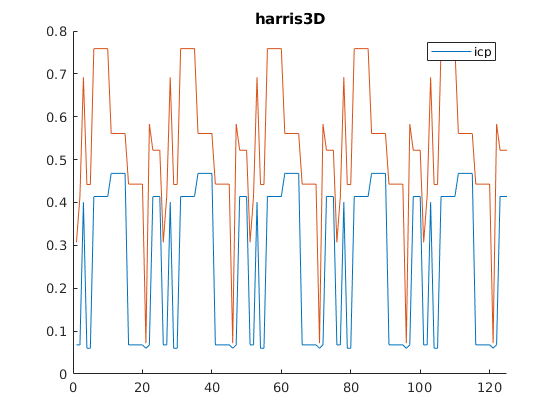


figure;
hold on;
plot(harris3D_dist_icp)
plot(harris3D_dist)
xlim([0 length(harris3D_dist)])
title('harris3D')
legend('icp')

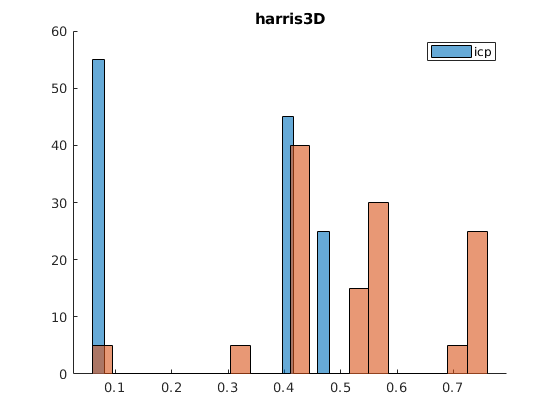


figure;
hold on;
histogram(harris3D_dist_icp,20)
histogram(harris3D_dist,20)
title('harris3D')
legend('icp')

hold off;



%% harris6D
% clc;close all;
harris6D_index_icp = find(kpts_types_icp == 'harris6D');
harris6D_dist_icp = (dist_mm_icp(harris6D_index_icp(1,1):harris6D_index_icp(length(harris6D_index_icp),1),1));
harris6D_min_dist_icp = min(harris6D_dist_icp)

harris6D_min_dist_icp = 0.1220

harris6D_max_dist_icp = max(harris6D_dist_icp)

harris6D_max_dist_icp = 19.2180

harris6D_middle_dist_icp = media(harris6D_dist_icp)

harris6D_middle_dist_icp = 5.8158

harris6D_nan_values_icp = length(find(isnan(harris6D_dist_icp) == 1))

harris6D_nan_values_icp = 0


harris6D_index = find(kpts_types == 'harris6D');
harris6D_dist = (dist_mm(harris6D_index(1,1):harris6D_index(length(harris6D_index),1),1));
harris6D_min_dist = min(harris6D_dist)

harris6D_min_dist = 0.0700

harris6D_max_dist = max(harris6D_dist)

harris6D_max_dist = 37.9260

harris6D_middle_dist = media(harris6D_dist)

harris6D_middle_dist = 10.2151

harris6D_nan_values = length(find(isnan(harris6D_dist) == 1))

harris6D_nan_values = 0

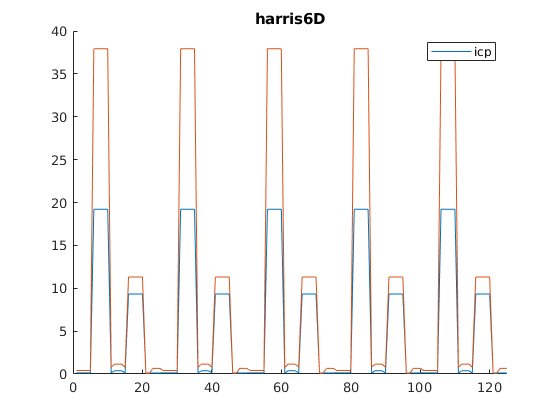


figure;
hold on;
plot(harris6D_dist_icp)
plot(harris6D_dist)
xlim([0 length(harris6D_dist)])
title('harris6D')
legend('icp')

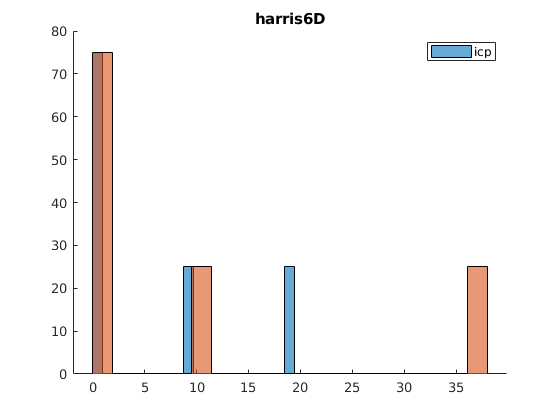


figure;
hold on;
histogram(harris6D_dist_icp,20)
histogram(harris6D_dist,20)
title('harris6D')
legend('icp')

hold off;



%% sift
%

clc;close all;


sift_index_icp = find(kpts_types_icp == 'sift_color');
sift_dist_icp = (dist_mm_icp(sift_index_icp(1,1):sift_index_icp(length(sift_index_icp),1),1));
sift_min_dist_icp = min(sift_dist_icp)

sift_min_dist_icp = 0.2730

sift_max_dist_icp = max(sift_dist_icp)

sift_max_dist_icp = 15.3260

sift_middle_dist_icp = media(sift_dist_icp)

sift_middle_dist_icp = 11.5628

sift_nan_values_icp = length(find(isnan(sift_dist_icp) == 1))

sift_nan_values_icp = 25


sift_index = find(kpts_types == 'sift_color');
sift_dist = (dist_mm(sift_index(1,1):sift_index(length(sift_index),1),1));
sift_min_dist = min(sift_dist)

sift_min_dist = 0.1580

sift_max_dist = max(sift_dist)

sift_max_dist = 37.9260

sift_middle_dist = media(sift_dist)

sift_middle_dist = 28.4840

sift_nan_values = length(find(isnan(sift_dist) == 1))

sift_nan_values = 25

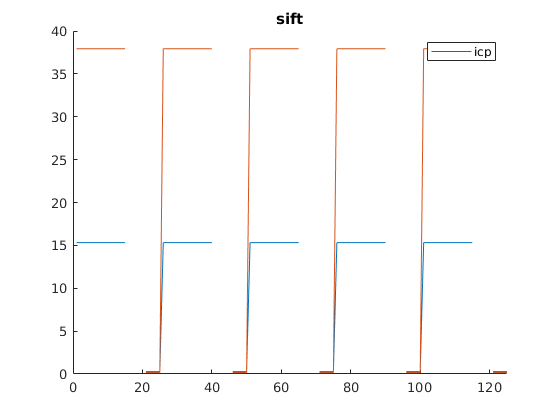


figure;
hold on;
plot(sift_dist_icp)
plot(sift_dist)
xlim([0 length(sift_dist)])
title('sift')
legend('icp')

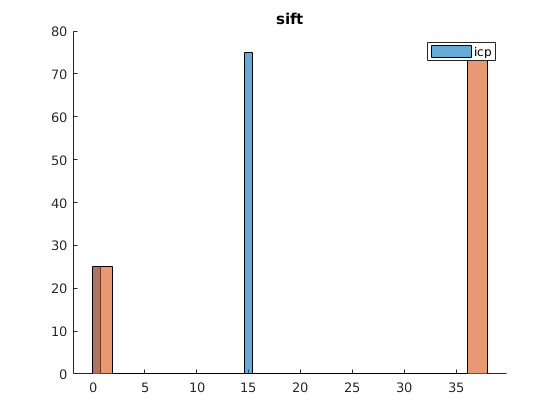


figure;
hold on;
histogram(sift_dist_icp,20)
histogram(sift_dist,20)
legend('icp')
title('sift')

hold off;